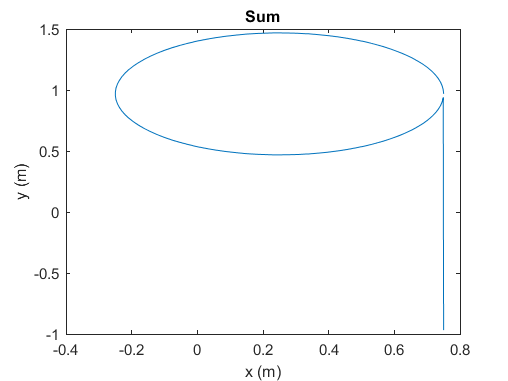

clc
clear all

% CINEMATICA DIRETTA
beta = linspace(0,2*pi,100); alpha = linspace(0,2*pi,100);
flag_1 = 0; flag_2 = 0;

% LINK DIMENSIONS [m]
l0 = 2; l1 = 0.5; l2 = 0.5; l3 = 1; l4 = 1;
L=[l0; l1; l2; l3; l4]'; % Configurazione singolare

% Posizione gomito A
center_x = 0; center_y = 0; radius = l1;
x_a = radius*cos(alpha) + center_x; y_a = radius * sin(alpha) + center_y;

% Somma link 2 
for i=1:length(beta)
    % Posizione gomito B
    x_b = l0+l2*cos(beta); y_b = l2*sin(beta);
    for j=1:length(alpha)
        % Distanza A-B
        array_q(j) = abs(sqrt((x_a(j)-x_b(i))^2+(y_a(j)-y_b(i))^2)-(l3+l4));
    end
    [minimum, index] = min(array_q);
    if minimum < 0.000001
        singularity_1(i,:) = [beta(i) alpha(index)];
        flag_1 = flag_1 +1;
    end
end
if flag_1>0
    for i=1:length(singularity_1)
        s_1(i,:) = direct_kinematics([singularity_1(i,:) 0],L,[singularity_1(i,1),singularity_1(i,2)]);
    end
    figure
    plot(s_1(:,1),s_1(:,2))
    xlabel("x (m)"); ylabel("y (m)");
    title("Sum")
end

l0 = 0.2; l1 = 0.5; l2 = 1.2; l3 = 0.5; l4 = 0.4;
L=[l0; l1; l2; l3; l4]'; % Configurazione singolare

% Differenza link 2
for i=1:length(beta)
    % Posizione gomito B
    x_b = l0+l2*cos(beta); y_b = l2*sin(beta);
    for j=1:length(alpha)
        % Distanza A-B
        array_q(j) = abs(sqrt((x_a(j)-x_b(i))^2+(y_a(j)-y_b(i))^2)-abs(l3-l4));
    end
    [minimum, index] = min(array_q);
    if minimum < 0.000001
        singularity_2(i,:) = [beta(i) alpha(index)];
        flag_2 = flag_2+1;
    end
end

if flag_2>0
    for i=1:length(singularity_2)
        s_2(i,:) = direct_kinematics([singularity_2(i,:) 0],L,[singularity_2(i,1),singularity_2(i,2)]);
    end
    figure
    plot(s_2(:,1),s_2(:,2))
    xlabel("x (m)"); ylabel("y (m)");
    title("Difference")
end



% CINEMATICA INVERSA
x_2 = l0; y_2=0;
index_s=1;
for i=1:length(beta)
    % Posizione gomito B
    x_b = l0+l1*cos(beta); y_b = l1*sin(beta);
    for j=1:length(alpha)
        s_1(j,:)= singularity_of_direct_kinematics([alpha(j) beta(i) 0],L,[alpha(j) beta(i)]);
        % Retta passante (x_2,y_2) e (x,y)
        m = (s_1(j,2)-y_2)/(s_1(j,1)-x_2);
        if ((y_b-y_2)-m*(x_b-x_2))< 0.000001
           array_s_1(index_s,:) = [s_1(j,1) s_1(j,2)];
           index_s = index_s+1;
        end
    end
end



x_1 = 0; y_1=0;
index_s=1;
for i=1:length(alpha)
    % Posizione gomito B
    x_a = l1*cos(alpha); y_a = l1*sin(alpha);
    for j=1:length(beta)
        s_1(j,:)= singularity_of_direct_kinematics([alpha(j) beta(i) 0],L,[alpha(j) beta(i)]);
        % Retta passante (x_2,y_2) e (x,y)
        m = (s_1(j,2)-y_1)/(s_1(j,1)-x_1);
        if ((y_a-y_1)-m*(x_a-x_1))< 0.000001
           array_s_2(index_s,:) = [s_1(j,1) s_1(j,2)];
           index_s = index_s+1;
        end
    end
end
